### Labo B: Analyse van digitale filters

#### Eerste orde IIR filter

IIR filter met volgende vergelijking: $y(n) = x(n) + a_{1}y(n-1)$

a1 = [0.1 0.9 1 1.1];
x = ones([1, 10]);

Teken de topologie:

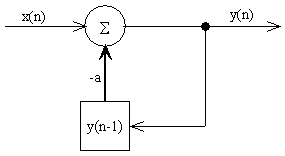

Wegens terugkoppeling is dit een IIR netwerk.

Als we manueel de eerste 4 samples van y(n) berekenen:

for n = 1:length(a1)
    y(n, 1) = x(1) + a1(n) * 0;
    for i = 2:length(x)
        y(n, i) = x(i) + a1(n) * y(n, i-1);
    end
end
y

y = 1.0e+42 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -

Voor de limietwaarden is deze:

for i = 1:length(a1)
    lim(i) = 1/ (1 - a1(i));
end
lim

lim =     1.1111   10.0000       Inf  -10.0000


De stapresponsie van een eerste orde analoog laagdoorlaat filter:


$$y\left(n\right)=a\left(1-e^{\frac{t}{\tau }} \right)$$


De stapresponsie van een digitaal ldl filter:


$$y\left(n\right)=a^{\tau }$$



$$\tau =-a_t$$


Laten we dit nu implementeren in Matlab en analyseren:

Geef x = 200 samples van waarde 1, filter en bewijs bovenstaande nummers.

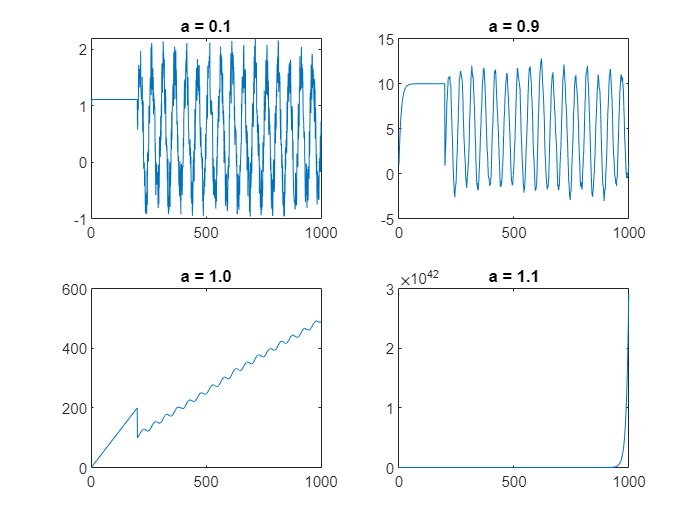

x = ones([1, 200]);
for n = 1:length(a1)
    y(n, 1) = x(1) + a1(n) * 0;
    for i = 2:length(x)
        y(n, i) = x(i) + a1(n) * y(n, i-1);
    end
end
subplot(2, 2, 1);
plot(y(1, :))
title('a = 0.1');
subplot(2, 2, 2);
plot(y(2, :))
title('a = 0.9');
subplot(2, 2, 3);
plot(y(3, :))
title('a = 1.0');
subplot(2, 2, 4);
plot(y(4, :))
title('a = 1.1');

Pas nu je signaal aan, en sample volgende golfvorm met een frequentiefs= 1000 Hz tussen t= 0 sent= 1 s:

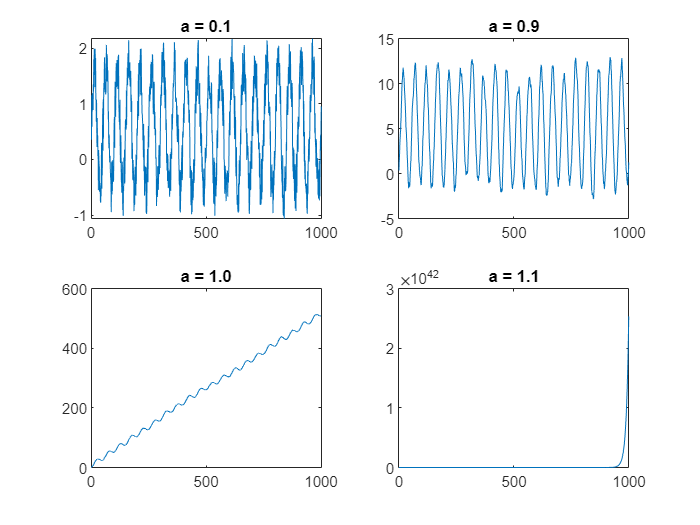

figure;
fs = 1000;
Ts = 1/fs;
p = 20;
n = rand([1, 1001]);
t = (0:Ts:1);
x = sin(2 * pi * p * t) + n;
for n = 1:length(a1)
    y(n, 1) = x(1) + a1(n) * 0;
    for i = 2:length(x)
        y(n, i) = x(i) + a1(n) * y(n, i-1);
    end
end
subplot(2, 2, 1);
plot(y(1, :))
title('a = 0.1');
subplot(2, 2, 2);
plot(y(2, :))
title('a = 0.9');
subplot(2, 2, 3);
plot(y(3, :))
title('a = 1.0');
subplot(2, 2, 4);
plot(y(4, :))
title('a = 1.1');

figure;

We zien duidelijk dat hoe hoger we a1 hebben, hoe minder hoge frequenties voorkomen in het signaal.

De Z-transformatie is: $H(z) = \frac{z}{z - a_{1}}$

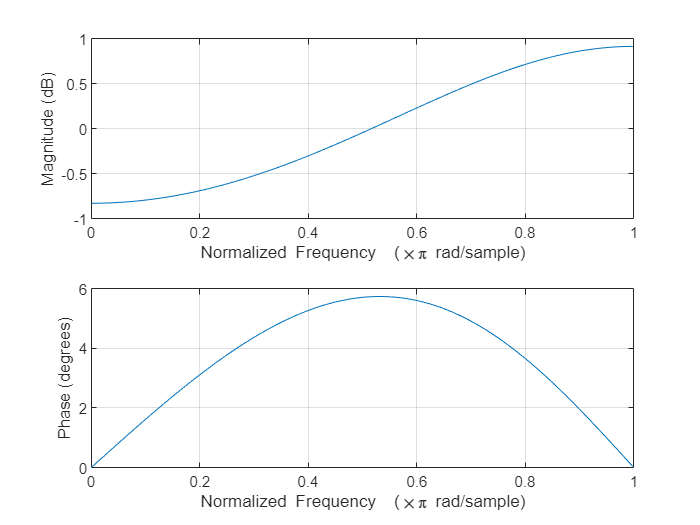

freqz(1, [1,a1(1)])

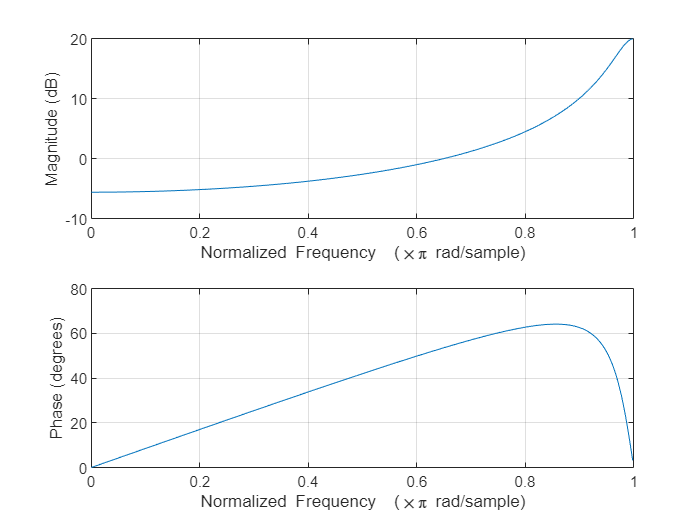

freqz(1, [1,a1(2)])

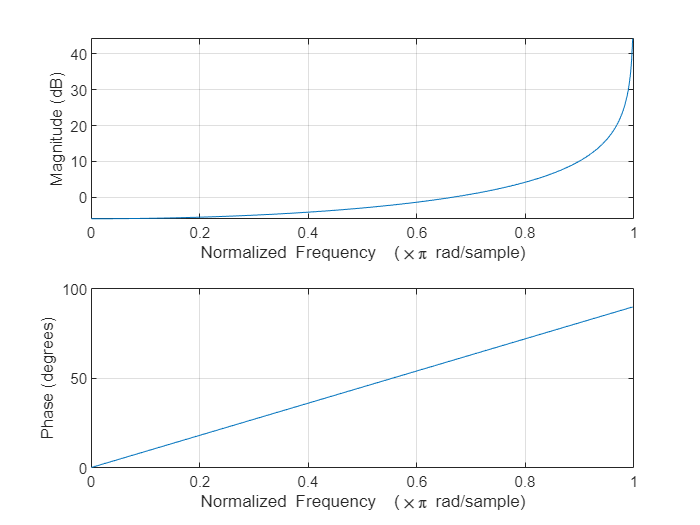

freqz(1, [1,a1(3)])

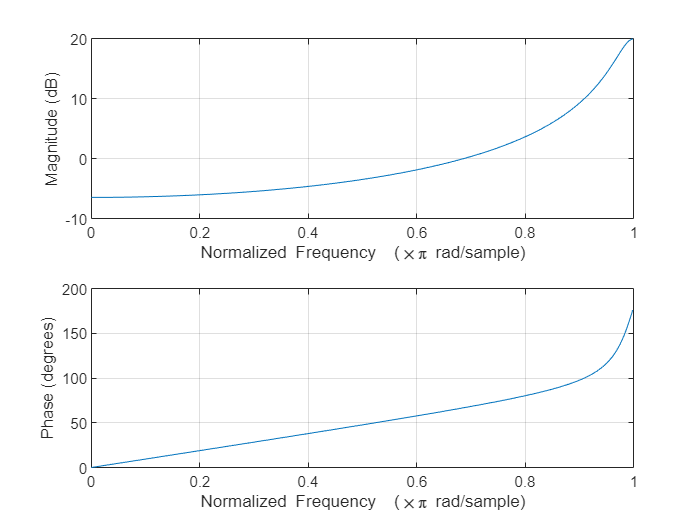

freqz(1, [1,a1(4)])

Beeld de polen en zeros af in matlab.

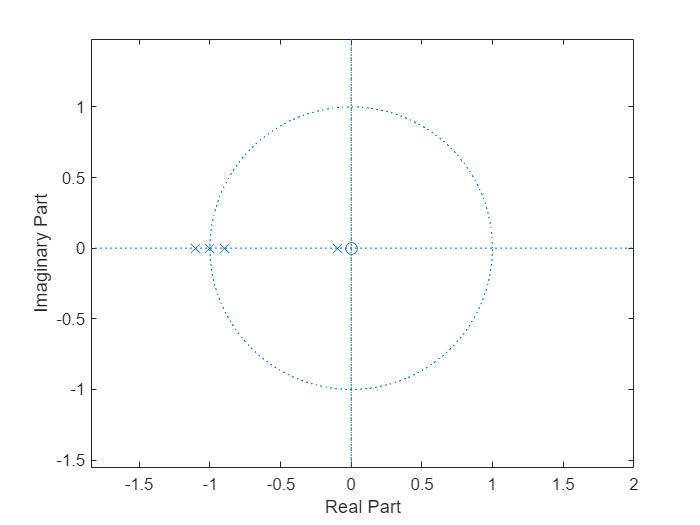

zplane(1, [1, a1(1)])
hold on;
zplane(1, [1, a1(2)])
hold on;
zplane(1, [1, a1(3)])
hold on;
zplane(1, [1, a1(4)])
hold off;

xlim([-1.84 2.00])
ylim([-1.55 1.48])

Beeld amplitude en faseresponsie af in discrete frequentiedomein.

Zie eerder.

Dit is onstabiel wanneer het op/buiten de eenheidscirkel valt.

### Tweede orde IIR filter

a1 = -0.96;
a2 =  0.25;
% y(i) = x(i) - a1 * y(i - 1) - a2 * y(i - 2);


H = tf([1, 0, 0], [1, a1, a2]);
r = abs(pole(H))

r =     0.5000
    0.5000


p = angle(pole(H))

p =     0.2838
   -0.2838


Beeld de liggin van deze polen af in het z-vlak

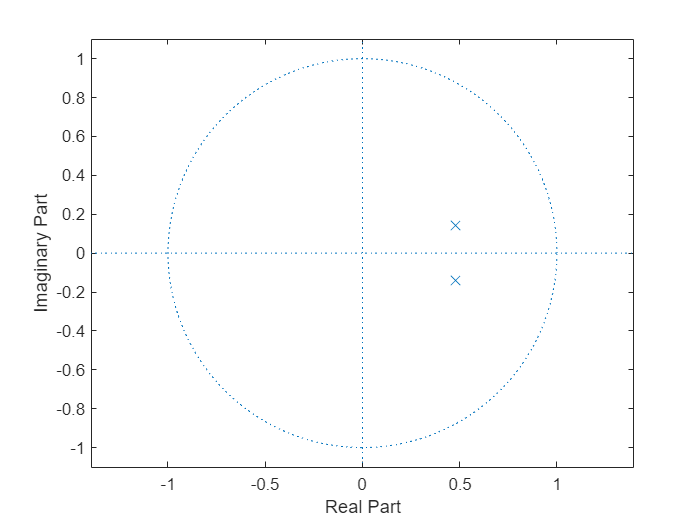

zplane([], pole(H))

Geef frequentieweergave:

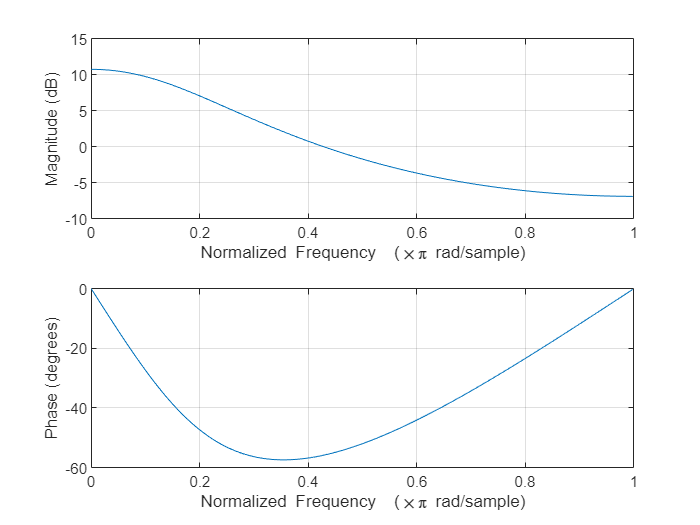

freqz([1 0 0], [1 a1 a2])

De polen hun invloed is het signaal omhoogtrekken, dit is hier zichtbaar als we de frequentie bekijken in stijgende zin.

De invloed van de polen vermindert en dus gaat het signaal verder dalen.

De resonantiepiek is:

cosTheta = cos(angle(pole(H))) .* ((1 + abs(pole(H)).^2)/(2 * abs(pole(H))))

cosTheta =     1.2000         0
    1.2000         0


Hr = (1/1-abs(pole(H)).^2) * (1/sin(angle(pole(H))))

Hr =     2.6786         0
    2.6786         0


z = [1 j -1];
for i = 1:length(z)
    Hs(i) = (z(i)^2)/(z(i)^2 + a1 * z(i) + a2);
end
Hs

Hs =    3.4483 + 0.0000i   0.5054 - 0.6469i   0.4525 + 0.0000i


Laat matlab poolfreq berekenen met fs = 8kHz

fs = 8000;
phase_pool = p(1)/pi;
ph = phase_pool * fs

ph = 722.6758

Welk soort iflter betreft het hier? LDL aangezien hij meer onderdrukt op hogere frequenties.

Laat rp naar 1 evolueren, wat is invloed van ligging van de polen op de freqweergave?

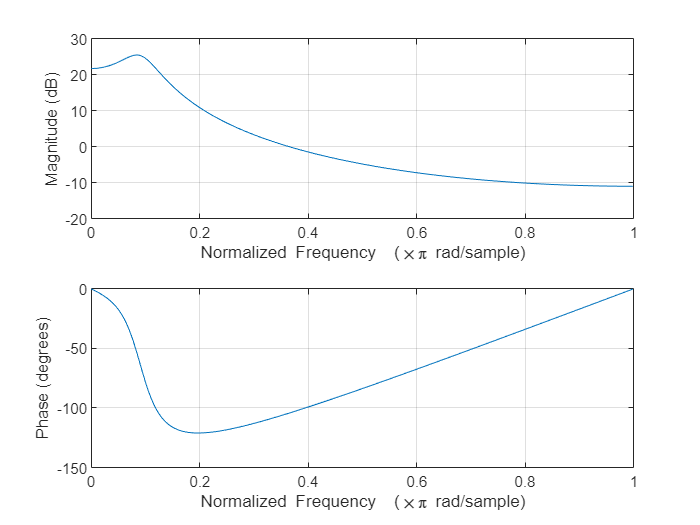

rp = [0.9, 0.99];
coef = poly([rp(1).*exp(1i * p(1)) rp(1).*exp(1i * -p(1))]);
freqz([1 0 0], coef);

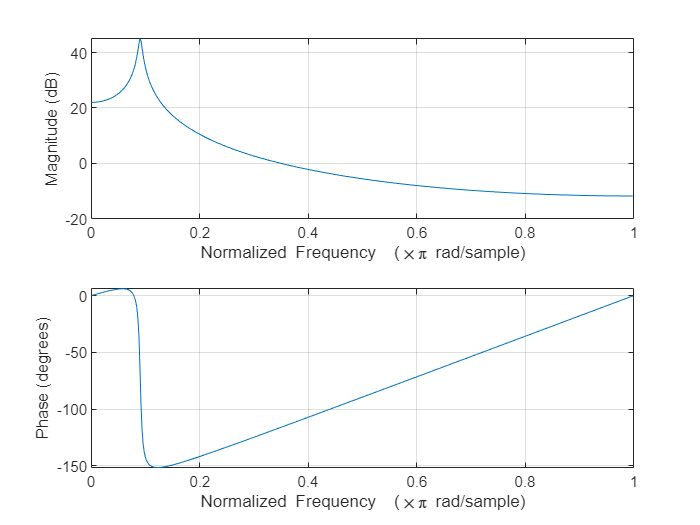

coef = poly([rp(2).*exp(1i * p(1)) rp(2).*exp(1i * -p(1))]);
freqz([1 0 0], coef);

Hoe verder de pool naar de eenheidscirkel, hoe hoger de piek in amplitude en hoe feller de faseverandering.

Laat nu sigmaPhi tussen 0 en 180 graden evolueren.

sigma = [0, pi/2, pi];
r = abs(pole(H))

r =     0.5000
    0.5000


coef = poly([r(1) * exp(1i * sigma(1)) r(1) * exp(1i * -sigma(1))])

coef =     1.0000   -1.0000    0.2500


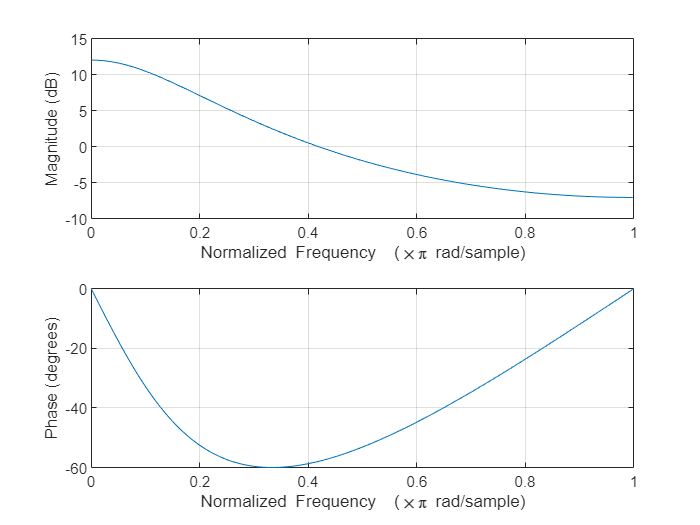

freqz([1 0 0], coef);

coef = poly([r(1) * exp(1i * sigma(2)) r(1) * exp(1i * -sigma(2))])

coef =     1.0000   -0.0000    0.2500


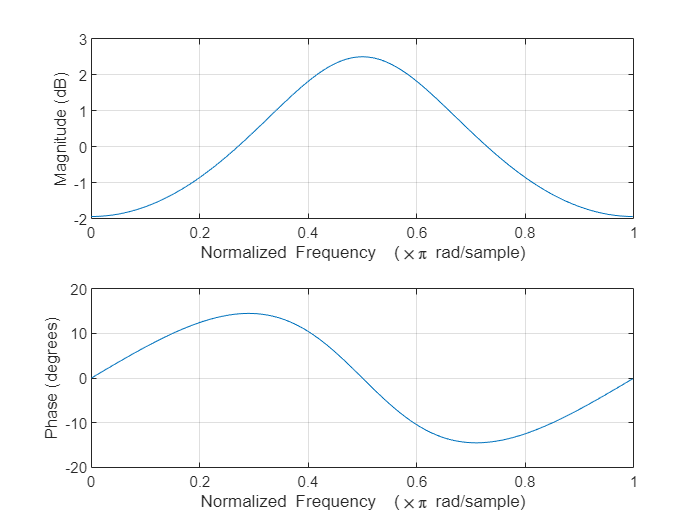

freqz([1 0 0], coef);

coef = poly([r(1) * exp(1i * sigma(3)) r(1) * exp(1i * -sigma(3))])

coef =     1.0000    1.0000    0.2500


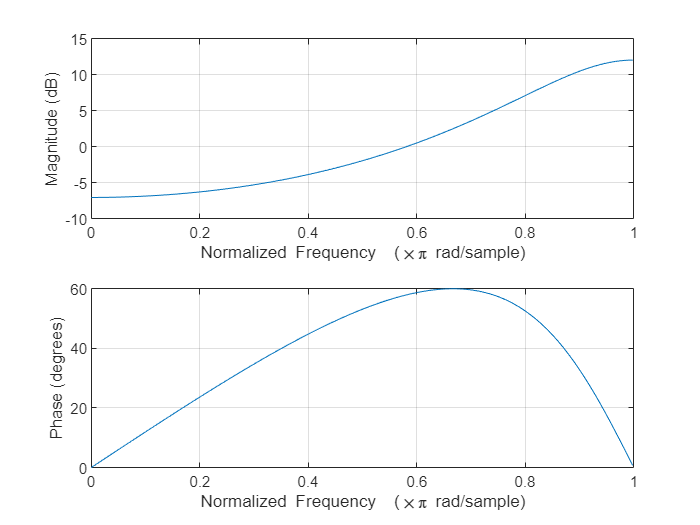

freqz([1 0 0], coef);

Naamate de poolhoek vergroot zal de amplitudepiek verhogen en naar rechts schuiven.

#### Plot de stap- en impulsresponsie van eenzelfde 2de orde IIR-netwerk:

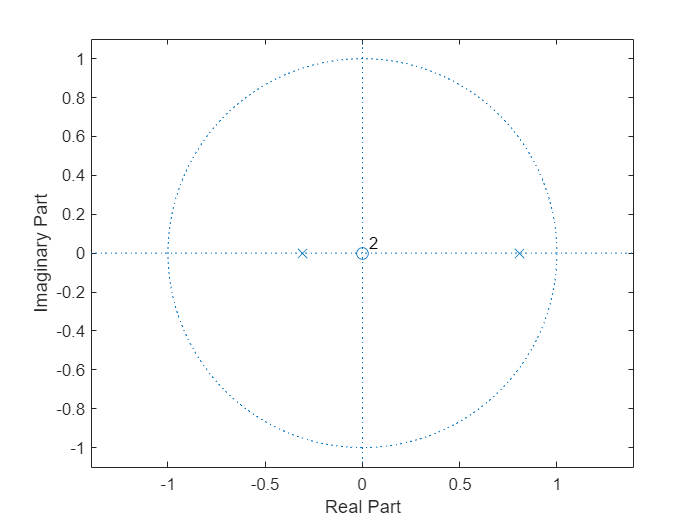

z = [1 0 0];
b1 = 0.5;
b2 = 0.25;
p = [1 -b1 -b2];
zplane(z, p)

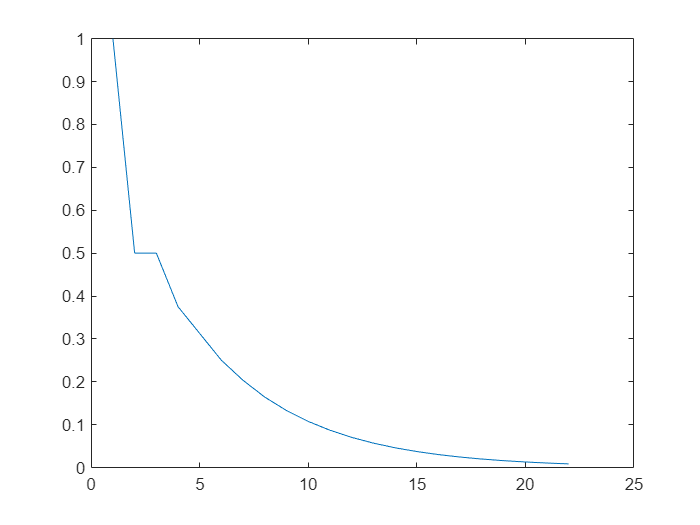

x = [1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];
plot(filter(z, p, x))

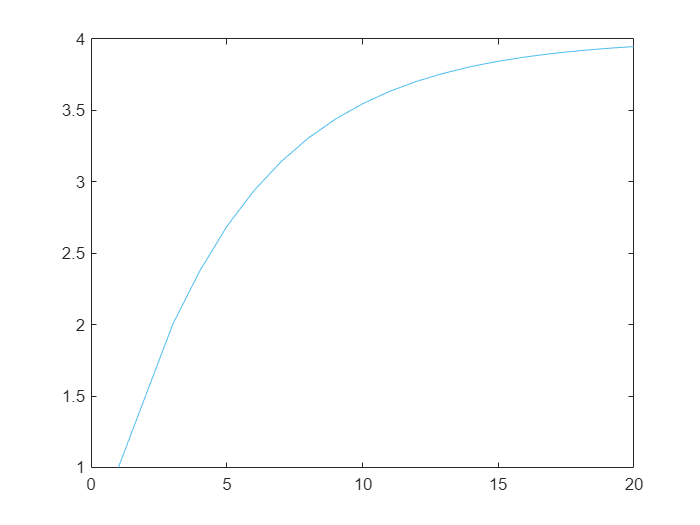

x = ones(20);
plot(filter(z, p, x))

Aangezien men enkel reele polen heeft, komt er geen oscilatie voor in de impulsresponsie.

De DC-versterking wordt gelijk aan 4.

## Tweede order FIR filter

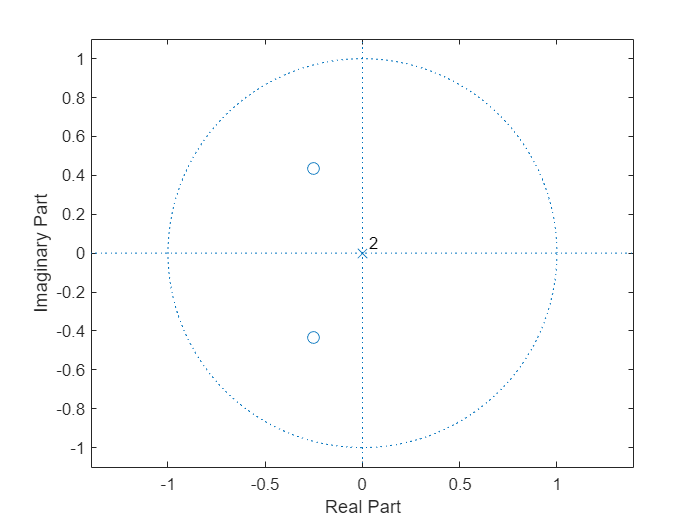

b1 = 0.5;
b2 = 0.25;
nul = [1 b1 b2];
pol = [1 0 0];
H = tf(nul, pol, 1);
zplane(nul, pol)

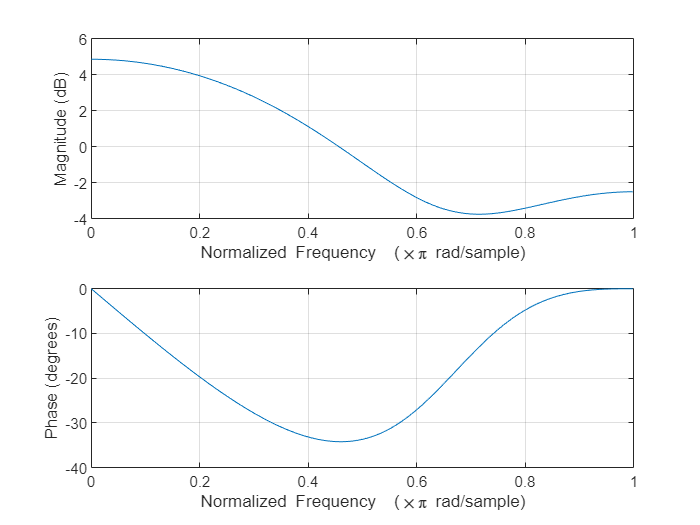

freqz(nul, pol)

De invloed van de nulpunten is het dal bij de frequentie 0.7 * fs.

Resonantiepiek:

Hr = (1 - b2) * sqrt((4 * b2 - b1^2)/(4 * b2))

Hr = 0.6495

Bereken H(DC), H(hs/4), H(fs/c):

z = [1 1j -1];
for i = 1:length(z)
    Hs(i) = (z(i)^2 + b1 * z(i) + b2)/z(i)^2; 
end
Hs

Hs =    1.7500 + 0.0000i   0.7500 - 0.5000i   0.7500 + 0.0000i


Bereken de de zerofrequentie indien fs = 8kHz

hoek = angle(zero(H));
fs = 8000;
phase_pool = hoek/pi;
ph = phase_pool * fs/2

ph = 1.0e+03 *

    2.6667
   -2.6667


Dit is een LDL filter

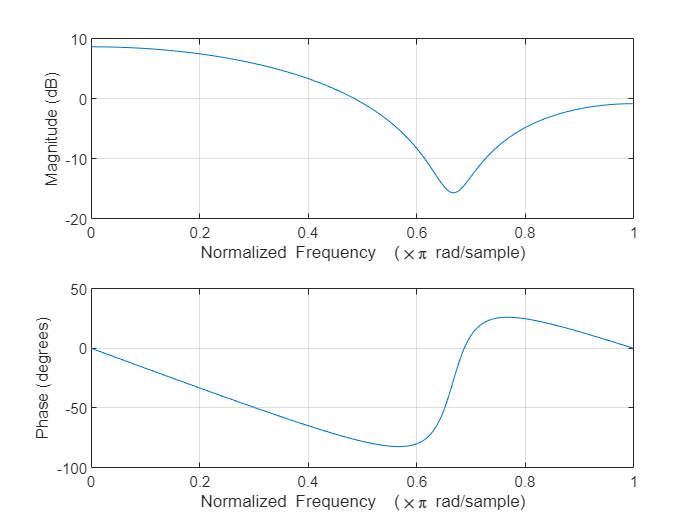

rp = [0.9, 0.99];
p = angle(zero(H));
coef = poly([rp(1).*exp(1i * p(1)) rp(1).*exp(1i * -p(1))]);
freqz(coef, [1 0 0]);

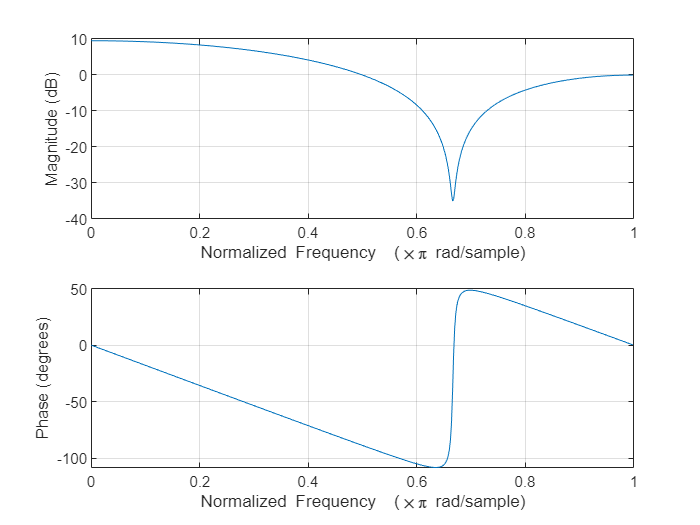

coef = poly([rp(2).*exp(1i * p(1)) rp(2).*exp(1i * -p(1))]);
freqz(coef, [1 0 0]);

Het dal is dieper, de faseverandering is plotser.

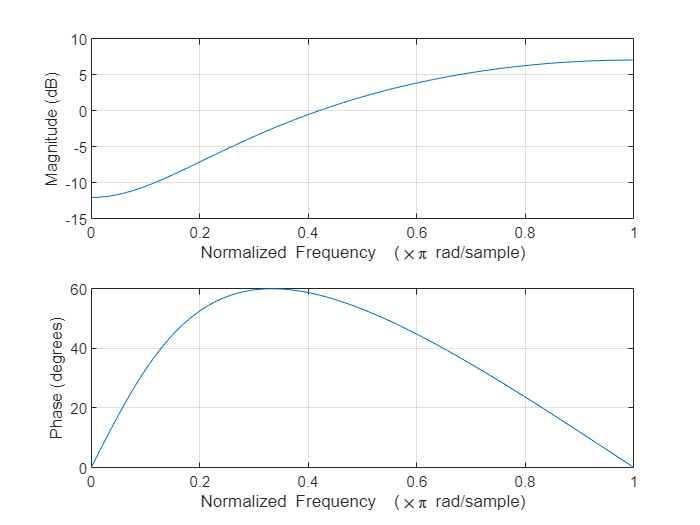

sigma = [0, pi/2, pi];
r = abs(zero(H));
coef = poly([r(1) * exp(1i * sigma(1)) r(1) * exp(1i * -sigma(1))]);
freqz(coef, [1 0 0]);

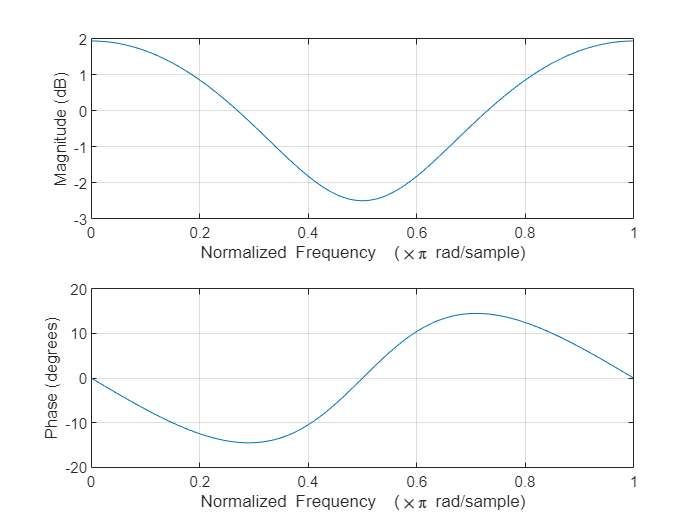

coef = poly([r(1) * exp(1i * sigma(2)) r(1) * exp(1i * -sigma(2))]);
freqz(coef, [1 0 0]);

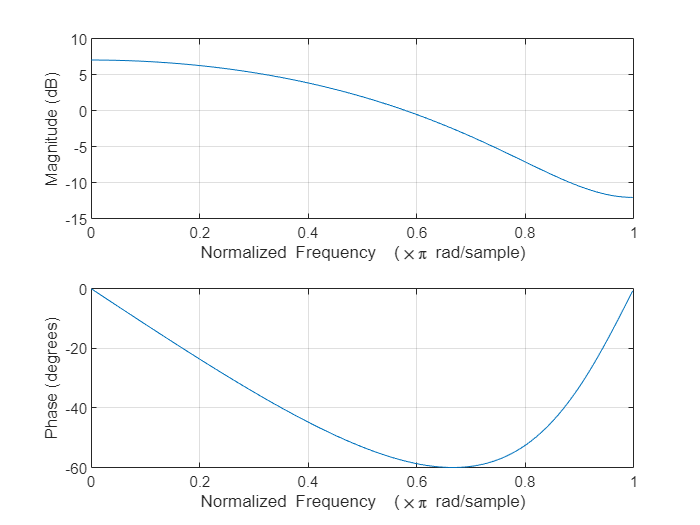

coef = poly([r(1) * exp(1i * sigma(3)) r(1) * exp(1i * -sigma(3))]);
freqz(coef, [1 0 0]);

Het dal wordt verschoven naar rechts.

Plot impulsresponsie van het FIR-netwerk.

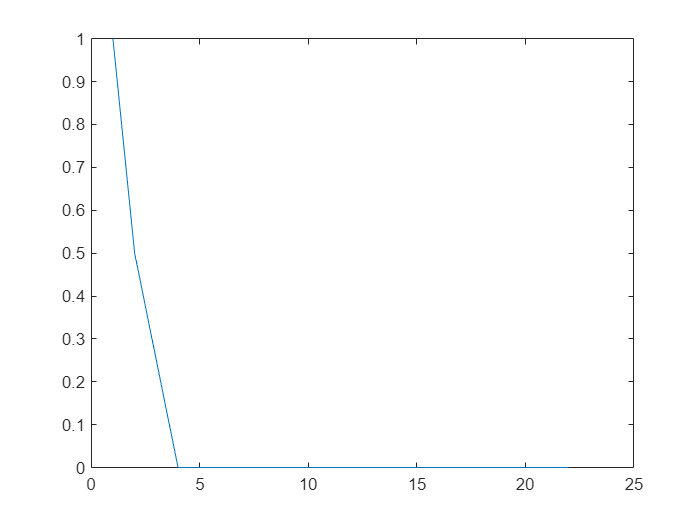

x = [1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];
plot(filter(nul, pol, x))

Het FIR-netwerk gaat veel steiler naar 0, er is geen exponentiele daling, er is geen terugkoppeling en dus zal het signaal minder lang in het systeem blijven hangen.